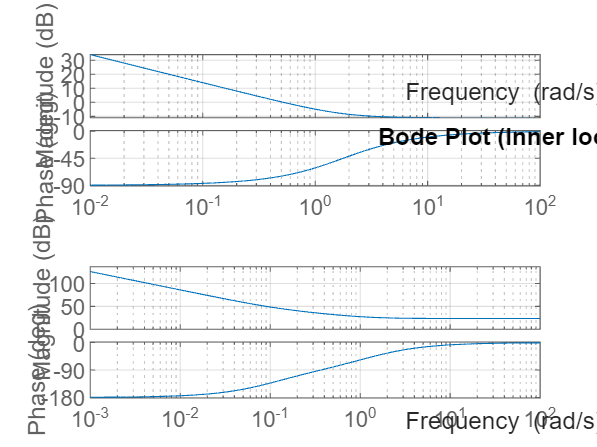

% === Drone XY Cascade Simulation with Optional I-Term ===
clear; clc;
s = tf('s');
g = 9.80665;

% === Plant Transfer Functions ===
G_outer = 1/s;   % Position → Velocity
G_inner = g/s;   % Velocity → Accel (Roll/Pitch)

% === USER INPUTS ===
use_manual_gains = true;  % Set to false to use auto-design

if use_manual_gains
    % === Manual Gain Input ===
    % Outer loop (Position PD)
    Kp_pos = 0.5;     
    Kd_pos = 0.3;

    % Inner loop (Velocity PID)
    Kp_vel = 2.0;     
    Kd_vel = 1.5;     
    Ki_vel = 0.2;     % ← Set to 0 to use PD only

    % Define Inner Controller (PD or PID based on Ki)
    if Ki_vel ~= 0
        D_inner = Kd_vel * s + Kp_vel + Ki_vel / s;
    else
        D_inner = Kd_vel * s + Kp_vel;
    end

    % Outer Controller
    D_outer = Kd_pos * s + Kp_pos;

else
    % === Automatic Gain Design (PD only) ===
    OS_pos = 20;     
    T_s_pos = 5;     
    frac = 4;        

    OS_vel = OS_pos / frac;
    T_s_vel = T_s_pos / frac;

    % Outer Loop (Position PD)
    zeta_pos = -log(OS_pos/100)/sqrt(pi^2 + log(OS_pos/100)^2);
    omega_n_pos = 4 / (zeta_pos * T_s_pos);
    pole_pos = -zeta_pos*omega_n_pos + 1i*omega_n_pos*sqrt(1 - zeta_pos^2);
    G_at_pole_outer = evalfr(G_outer, pole_pos);
    phi_pos = pi - angle(G_at_pole_outer);
    z_c_pos = real(pole_pos) + imag(pole_pos) / tan(phi_pos);
    Kd_pos = 1 / abs((pole_pos + z_c_pos) * G_at_pole_outer);
    Kp_pos = Kd_pos * z_c_pos;
    D_outer = abs(Kd_pos) * (s + abs(z_c_pos));

    % Inner Loop (Velocity PD only)
    zeta_vel = -log(OS_vel/100)/sqrt(pi^2 + log(OS_vel/100)^2);
    omega_n_vel = 4 / (zeta_vel * T_s_vel);
    pole_vel = -zeta_vel*omega_n_vel + 1i*omega_n_vel*sqrt(1 - zeta_vel^2);
    G_at_pole_inner = evalfr(G_inner, pole_vel);
    phi_vel = pi - angle(G_at_pole_inner);
    z_c_vel = real(pole_vel) + imag(pole_vel) / tan(phi_vel);
    Kd_vel = 1 / abs((pole_vel + z_c_vel) * G_at_pole_inner);
    Kp_vel = Kd_vel * z_c_vel;
    D_inner = abs(Kd_vel) * (s + abs(z_c_vel));
    Ki_vel = 0;
end

% === Closed-Loop System ===
Inner_CL = feedback(D_inner * G_inner, 1);
Outer_CL = feedback(D_outer * G_outer * Inner_CL, 1);

% === Bode Plots ===
figure;
subplot(2,1,1);
bode(D_outer * G_outer * Inner_CL);
title('Bode Plot (Outer loop)');
grid on;

subplot(2,1,2);
bode(D_inner * G_inner);
title('Bode Plot (Inner loop)');
grid on;

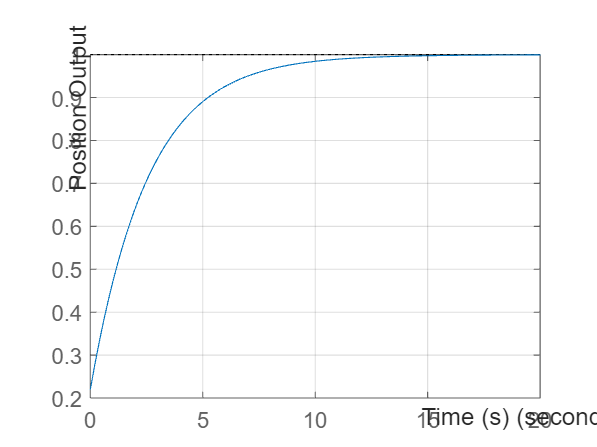


% === Step Response ===
figure;
step(Outer_CL, 20);
title('Step Response of Full Cascaded System');
xlabel('Time (s)');
ylabel('Position Output');
grid on;


% === Step Info Summary ===
step_info = stepinfo(Outer_CL);

% === Stability Check ===
poles_outer = pole(Outer_CL);
if max(real(poles_outer)) >= 0
    fprintf('Warning: The outer loop is unstable.\n');
else
    fprintf('Outer loop is stable.\n');
end

Outer loop is stable.



% === Display Gains ===
fprintf('\n--- Controller Gains ---\n');


--- Controller Gains ---


fprintf('Outer loop (Position → Velocity):  Kp = %.4f, Kd = %.4f\n', abs(Kp_pos), abs(Kd_pos));

Outer loop (Position → Velocity):  Kp = 0.5000, Kd = 0.3000


fprintf('Inner loop (Velocity → Roll/Pitch):  Kp = %.4f, Kd = %.4f, Ki = %.4f\n', ...
    abs(Kp_vel), abs(Kd_vel), abs(Ki_vel));

Inner loop (Velocity → Roll/Pitch):  Kp = 2.0000, Kd = 1.5000, Ki = 0.2000
